%% Filtre de Kalman 
% -----------------------------------------------------------------------------
% L'objectif est de generer une trajectoire que nous bruiterons plus tard
% afin d'appliquer le filtre de Kalman sur cette derniere et se rendre
% compte de ses performances.
% -----------------------------------------------------------------------------
clear, close all

% Paramètres du modèle
A = [1 1; 0 1];  % Matrice d'état
H = [1 0];      % Matrice d'observation

% Bruit du processus et de mesure
Q = 0.01 * eye(2);  % Covariance du bruit du processus
R = 0.1;            % Variance du bruit de mesure

% État initial et covariance
x0 = [0; 0];        % État initial
P0 = eye(2);        % Covariance initiale


% Génération de la trajectoire réelle (sans bruit)
T = 100;            % Nombre de points temporels
realTrajectory = zeros(2, T);
for t = 1:T
    % Étape de prédiction du modèle
    x_pred = A * x0;
    
    % Ajout de bruit de processus
    x0 = x_pred + sqrtm(Q) * randn(2, 1);
    
    realTrajectory(:, t) = x0;
end

% Génération de bruit de mesure
measurementNoise = sqrt(R) * randn(1, T);

% Mesures (trajectoire réelle + bruit de mesure)
measurements = H * realTrajectory + measurementNoise;

% Initialisation des variables du filtre de Kalman
x_hat = x0;  % Estimation initiale de l'état
P_hat = P0;  % Covariance initiale de l'estimation


% Filtrage de Kalman
filteredTrajectory = zeros(2, T);
for t = 1:T
    % Étape de prédiction du filtre de Kalman
    x_pred = A * x_hat;
    P_pred = A * P_hat * A' + Q;
    
    % Calcul de la ganache de Kalman
    K = P_pred * H' / (H * P_pred * H' + R);
    
    % Étape de mise à jour (correction) du filtre de Kalman
    x_hat = x_pred + K * (measurements(:, t) - H * x_pred);
    P_hat = (eye(2) - K * H) * P_pred;
    
    % Stockage de la trajectoire filtrée
    filteredTrajectory(:, t) = x_hat;
end


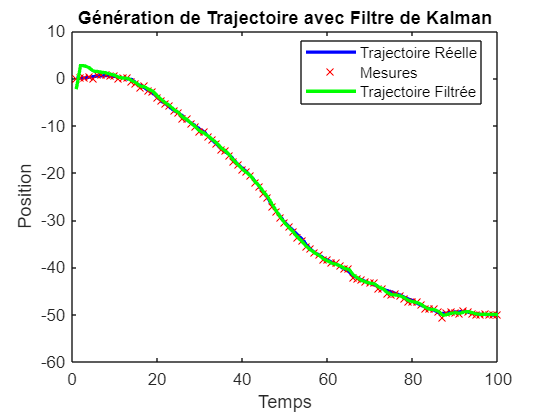

% Affichage des résultats
figure;
plot(1:T, realTrajectory(1, :), 'b', 'LineWidth', 2, 'DisplayName', 'Trajectoire Réelle');
hold on;
plot(1:T, measurements, 'rx', 'DisplayName', 'Mesures');
plot(1:T, filteredTrajectory(1, :), 'g', 'LineWidth', 2, 'DisplayName', 'Trajectoire Filtrée');
legend('Location', 'Best');
title('Génération de Trajectoire avec Filtre de Kalman');
xlabel('Temps');
ylabel('Position');